clear all
syms lambda rA rB R1 R2 R3 uA3 uB3 ;

r1=[12.412;-0.027;5.008];
u31=[0.231;0.776;0.587];
r2=[24.512;-0.027;5.008];
u32=[0.231;0.776;0.587];
r3=[15.818;12.447;9.722];
u33=[0.231;0.776;0.587];
r4=[3.718;12.447;9.722];
u34=[0.231;0.776;0.587];
r5=[13.352;-0.117;19.738];
u35=[0.231;0.776;0.587];


x1=[];
y1=[];
x2=[];
y2=[];
x3=[];
y3=[];
x4=[];
y4=[];
x5=[];
y5=[];

hold on
axis([0 15 0 15]);
for R3=2:0.3:13 %离心率
    R1=4;
     %椭球半轴长，R1=R2,R3是polar axis
    n=0.01; %模拟的步长精度

    miu2=cont(r1,r2,R1,R3,u31,u32);
    %cont(rA,rB,R1,R3,uA3,uB3)
    while miu2>1
        R1=R1+n;
        R3=R3;
        miu2=cont(r1,r2,R1,R3,u31,u32);
    end
    
    while miu2<1
        R1=R1-n;
        R3=R3;
        miu2=cont(r1,r2,R1,R3,u31,u32);
    end
    [R1,R3,miu2]
    x1=[x1,R1];
    y1=[y1,R3];   
end

ans =     8.2300    2.0000    1.0002


ans =     7.4100    2.3000    1.0004


ans =     6.9800    2.6000    1.0002


ans =     6.7100    2.9000    1.0019


ans =     6.5400    3.2000    1.0009


ans =     6.4200    3.5000    1.0001


ans =     6.3300    3.8000    1.0000


ans =     6.2600    4.1000    1.0004


ans =     6.2000    4.4000    1.0023


ans =     6.1600    4.7000    1.0016


ans =     6.1300    5.0000    1.0002


ans =     6.1000    5.3000    1.0007


ans =     6.0700    5.6000    1.0027


ans =     6.0500    5.9000    1.0027


ans =     6.0400    6.2000    1.0006


ans =     6.0200    6.5000    1.0023


ans =     6.0100    6.8000    1.0015


ans =     6.0000    7.1000    1.0012


ans =     5.9900    7.4000    1.0014


ans =     5.9800    7.7000    1.0019


ans =     5.9700    8.0000    1.0027


ans =     5.9700    8.3000    1.0005


ans =     5.9600    8.6000    1.0019


ans =     5.9600    8.9000    1.0001


ans =     5.9500    9.2000    1.0018


ans =     5.9500    9.5000    1.0004


ans =     5.9400    9.8000    1.0024


ans =     5.9400   10.1000    1.0012


ans =     5.9400   10.4000    1.0001


ans =     5.9300   10.7000    1.0024


ans =     5.9300   11.0000    1.0015


ans =     5.9300   11.3000    1.0006


ans =     5.9200   11.6000    1.0032


ans =     5.9200   11.9000    1.0025


ans =     5.9200   12.2000    1.0018


ans =     5.9200   12.5000    1.0012


ans =     5.9200   12.8000    1.0006



plot(x1,y1,'color',[221, 42, 22]/256, ...
    'LineWidth',1.5,'DisplayName','1-2')


for R1=3:0.3:13 %离心率
    R3=8;
     %椭球半轴长，R1=R2,R3是polar axis
    n=0.01; %模拟的步长精度

    miu2=cont(r1,r3,R1,R3,u31,u33);
    %cont(rA,rB,R1,R3,uA3,uB3)
    while miu2>1
        R1=R1;
        R3=R3+n;
        miu2=cont(r1,r3,R1,R3,u31,u33);
    end
    
    while miu2<1
        R1=R1;
        R3=R3-n;
        miu2=cont(r1,r3,R1,R3,u31,u33);
    end
    [R1,R3,miu2]
    x2=[x2,R1];
    y2=[y2,R3];   
end

ans =     3.0000    8.5200    1.0003


ans =     3.3000    8.0700    1.0005


ans =     3.6000    7.7700    1.0010


ans =     3.9000    7.5600    1.0010


ans =     4.2000    7.4000    1.0021


ans =     4.5000    7.2900    1.0003


ans =     4.8000    7.1900    1.0020


ans =     5.1000    7.1200    1.0011


ans =     5.4000    7.0600    1.0009


ans =     5.7000    7.0100    1.0010


ans =     6.0000    6.9700    1.0005


ans =     6.3000    6.9300    1.0017


ans =     6.6000    6.9000    1.0016


ans = 1×3
    6.9000    6.8800    1.0000


ans = 1×3
    7.2000    6.8500    1.0020


ans = 1×3
    7.5000    6.8300    1.0021


ans = 1×3
    7.8000    6.8200    1.0000


ans = 1×3
    8.1000    6.8000    1.0013


ans = 1×3
    8.4000    6.7900    1.0003


ans = 1×3
    8.7000    6.7700    1.0025


ans = 1×3
    9.0000    6.7600    1.0022


ans = 1×3
    9.3000    6.7500    1.0023


ans = 1×3
    9.6000    6.7400    1.0026


ans = 1×3
    9.9000    6.7400    1.0003


ans = 1×3
   10.2000    6.7300    1.0010


ans = 1×3
   10.5000    6.7200    1.0020


ans = 1×3
   10.8000    6.7200    1.0002


ans = 1×3
   11.1000    6.7100    1.0015


ans = 1×3
   11.4000    6.7000    1.0029


ans = 1×3
   11.7000    6.7000    1.0015


ans = 1×3
   12.0000    6.7000    1.0002


ans = 1×3
   12.3000    6.6900    1.0020


ans = 1×3
   12.6000    6.6900    1.0009


ans = 1×3
   12.9000    6.6800    1.0028



plot(x2,y2,'color',[29, 50, 67]/256, ...
    'LineWidth',1.5,'DisplayName','1-3')


for R1=7:0.3:13 %离心率
    R3=8;
     %椭球半轴长，R1=R2,R3是polar axis
    n=0.01; %模拟的步长精度

    miu2=cont(r1,r4,R1,R3,u31,u34);
    %cont(rA,rB,R1,R3,uA3,uB3)
    while miu2>1
        R1=R1;
        R3=R3+n;
        miu2=cont(r1,r4,R1,R3,u31,u34);
    end
    
    while miu2<1
        R1=R1;
        R3=R3-n;
        miu2=cont(r1,r4,R1,R3,u31,u34);
    end
    [R1,R3,miu2]
    x3=[x3,R1];
    y3=[y3,R3];   
end

ans = 1×3
    7.0000   10.1700    1.0003


ans = 1×3
    7.3000    9.1900    1.0002


ans = 1×3
    7.6000    8.5200    1.0005


ans = 1×3
    7.9000    8.0400    1.0000


ans = 1×3
    8.2000    7.6700    1.0001


ans = 1×3
    8.5000    7.3700    1.0013


ans = 1×3
    8.8000    7.1400    1.0007


ans = 1×3
    9.1000    6.9500    1.0000


ans = 1×3
    9.4000    6.7800    1.0013


ans = 1×3
    9.7000    6.6400    1.0017


ans = 1×3
   10.0000    6.5200    1.0019


ans = 1×3
   10.3000    6.4200    1.0013


ans = 1×3
   10.6000    6.3300    1.0013


ans = 1×3
   10.9000    6.2500    1.0014


ans = 1×3
   11.2000    6.1800    1.0012


ans = 1×3
   11.5000    6.1200    1.0004


ans = 1×3
   11.8000    6.0600    1.0012


ans = 1×3
   12.1000    6.0100    1.0009


ans = 1×3
   12.4000    5.9600    1.0018


ans = 1×3
   12.7000    5.9200    1.0013


ans = 1×3
   13.0000    5.8800    1.0017



plot(x3,y3,'color',[84, 130, 53]/256, ...
    'LineWidth',1.5,'DisplayName','1-4')


for R1=6.7:0.3:13 %离心率
    R3=8;
     %椭球半轴长，R1=R2,R3是polar axis
    n=0.01; %模拟的步长精度

    miu2=cont(r1,r5,R1,R3,u31,u35);
    %cont(rA,rB,R1,R3,uA3,uB3)
    while miu2>1
        R1=R1;
        R3=R3+n;
        miu2=cont(r1,r5,R1,R3,u31,u35);
    end
    
    while miu2<1
        R1=R1;
        R3=R3-n;
        miu2=cont(r1,r5,R1,R3,u31,u35);
    end
    [R1,R3,miu2]
    x4=[x4,R1];
    y4=[y4,R3];   
end

ans = 1×3
    6.7000    9.4300    1.0001


ans = 1×3
    7.0000    8.2600    1.0004


ans = 1×3
    7.3000    7.5300    1.0002


ans = 1×3
    7.6000    7.0200    1.0006


ans = 1×3
    7.9000    6.6500    1.0001


ans = 1×3
    8.2000    6.3600    1.0005


ans = 1×3
    8.5000    6.1300    1.0008


ans = 1×3
    8.8000    5.9400    1.0016


ans = 1×3
    9.1000    5.7900    1.0010


ans = 1×3
    9.4000    5.6600    1.0011


ans = 1×3
    9.7000    5.5500    1.0011


ans = 1×3
   10.0000    5.4500    1.0023


ans = 1×3
   10.3000    5.3700    1.0017


ans = 1×3
   10.6000    5.3000    1.0010


ans = 1×3
   10.9000    5.2300    1.0026


ans = 1×3
   11.2000    5.1800    1.0007


ans = 1×3
   11.5000    5.1300    1.0004


ans = 1×3
   11.8000    5.0800    1.0016


ans = 1×3
   12.1000    5.0400    1.0012


ans = 1×3
   12.4000    5.0000    1.0020


ans = 1×3
   12.7000    4.9700    1.0007


ans = 1×3
   13.0000    4.9400    1.0003


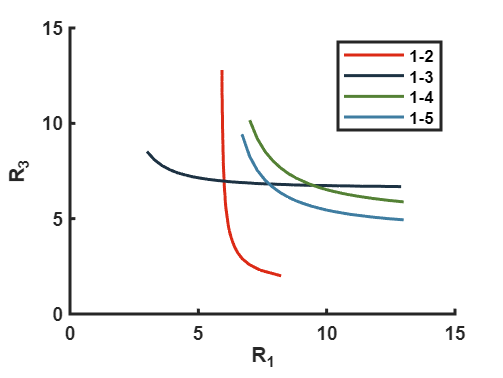


plot(x4,y4,'color',[63, 125, 162]/256, ...
    'LineWidth',1.5,'DisplayName','1-5')



set(gca,'linewidth',1.5,'FontWeight','bold','FontName','arial');
xlabel('R_1','FontName','arial','FontWeight','bold'); 
ylabel('R_3','FontName','arial','FontWeight','bold');
legend('Location','northeast');

hold off

function miu2=cont(rA,rB,R1,R3,uA3,uB3)
    syms lambda
    rAB=rB-rA;
    e=R3/R1;
    x=(1-lambda)*(1-e^2);
    y=lambda*(1-e^2);
    D=(1-x)*(1-y)-x*y*(dot(uA3,uB3))^2;
    alpha=x*(1-y)/D;
    beta=y*(1-x)/D;
    gama=x*y*(dot(uA3,uB3))/D;
    I=eye(3);
    C=(I+alpha*(uA3*uA3.')+beta*(uB3*uB3.')+gama*((uA3*uB3.')+(uB3*uA3.')))/(R1^2);
    F=lambda*(1-lambda)*(rAB.'*C*rAB);
    fun=@(lambda) -eval(F);
    [~,fval]=fminbnd(fun,0,1);
    miu2=-fval;
end

